# **椭圆极化波的演示**

**        在一般情况下，对于沿**$x$**方向传播的均匀平面波，其电场强度**$E$**的两个横向分量**$E_x$**和**$E_y$**的振幅与相位都不相同，即电场分量的瞬时值分别为**


$$\begin{array}{l}
E_y =E_{ym} \cos (\omega t-\beta x)\\
E_z =E_{zm} \cos (\omega t-\beta x-\psi )
\end{array}$$


**        在**$x=0$**的等相面上，则有**


$$\begin{array}{l}
E_y =E_{ym} \cos \omega t\\
E_z =E_{zm} \cos (\omega t-\psi )
\end{array}$$


**        为消去上面二式中的**$\omega t$**，可化为**


$$$$\cos\omega t=\frac{E_y}{E_{ym}}$$$$


**        则有**$$$\mathrm{sin}\omega t=\sqrt{1-\cos^{2}\omega t}=\sqrt{1-\frac{E_{y}^{2}}{E_{ym}^{2}}}$$$**，因此**


$$$$\frac{E_x}{E_{zm}}=\cos(\omega t-\psi)=\mathrm{cos}\omega t\mathrm{cos}\psi+\mathrm{sin}\omega t\mathrm{sin}\psi=\frac{E_y}{E_{_{jm}}\mathrm{cos}\psi}+\sqrt{1-\frac{E_y^2}{E_{_{jm}}^2}}\mathrm{sin}\psi $$$$


**即有**


$$$$\frac{E_{z}}{E_{zm}}-\frac{E_{y}}{E_{ym}}\mathrm{cos}\phi=\sqrt{1-\frac{E_{y}^{2}}{E_{ym}^{2}}}\mathrm{sin}\phi $$$$


**由此得**


$$$$\frac{E_y^2}{E_{\mathrm{ym}}^2}-\frac{2E_yE_x}{E_{\mathrm{ym}}E_{\mathrm{zm}}}\mathrm{cos}\psi+\frac{E_x^2}{E_{\mathrm{zm}}^2}=\mathrm{sin}^2\psi $$$$


**这是一个椭圆方程，此时，电磁波的极化形式为椭圆极化。**

## **一、沿x方向 phase = 0 传输时的右旋椭圆极化波MATLAB动画**

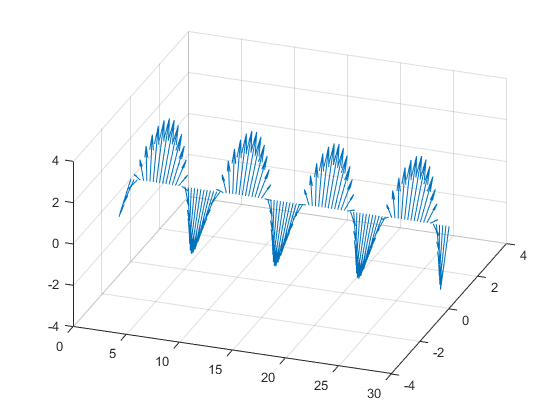

clc
clear
x=(0:0.3:30);                     	%传输距离
l=zeros(size(x)); 
t=0;                            	%时间变量
for i=1:150                      	%帧数
Eym=1;
Ezm=3;
omega=2*pi;
Ey=Eym*cos(omega*t-0.8*x);    	%电场横向分量
Ez=Ezm*cos(omega*t-0.8*x-pi/4); 	%电场横向分量
quiver3(x,l,l,l,Ey,Ez);           	%以(x,0,0)为起点画出传输方向上每一点的电场矢量图
axis([0,30,-4,4,-4,4]); view(20,40); 	%观察范围
mov(i)=getframe(gcf);           	%捕捉当前图像作为一帧
t=t+0.05;                     	%时间变量变化微小量
end
hold off;

- **动态展示**

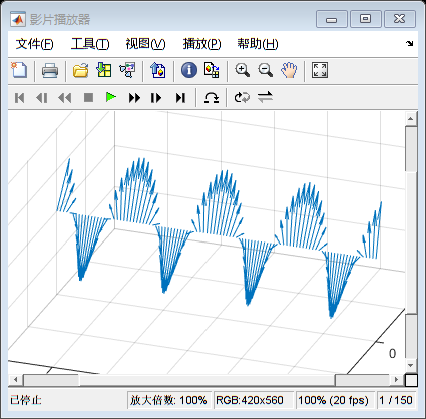

implay(mov);

- **保存为视频文件**

v=VideoWriter('右旋椭圆极化波.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)

## **二、沿x方向 phase = 0 传输时的左旋椭圆极化波MATLAB动画**

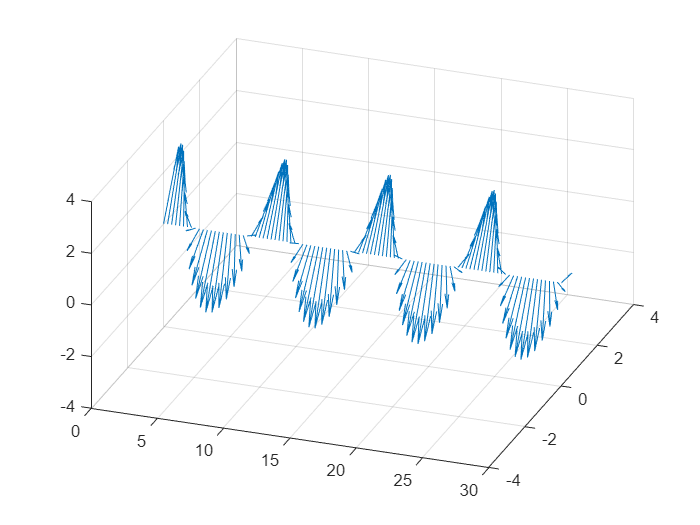

clc
clear
x=(0:0.3:30);                     	%传输距离
l=zeros(size(x)); 
t=0;                            	%时间变量
for i=1:500                      	%帧数
Eym=1;
Ezm=3;
omega=2*pi;
Ey=Eym*cos(omega*t-0.8*x);    	%电场横向分量
Ez=Ezm*cos(omega*t-0.8*x+pi/4); 	%电场横向分量
quiver3(x,l,l,l,Ey,Ez);           	%以(x,0,0)为起点画出传输方向上每一点的电场矢量图
axis([0,30,-4,4,-4,4]); view(20,40); 	%观察范围
mov(i)=getframe(gcf);           	%捕捉当前图像作为一帧；
t=t+0.05;                     	%时间变量变化微小量
end
hold off;

- **动态展示**

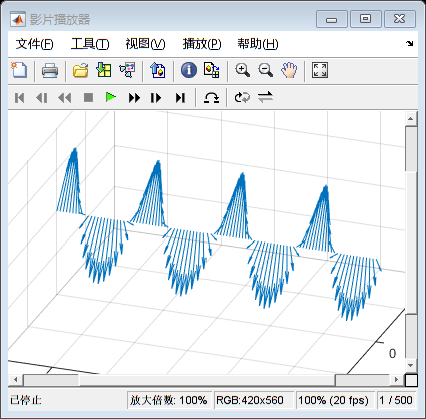

implay(mov);

- **保存为视频文件**

v=VideoWriter('左旋椭圆极化波.avi','Motion JPEG AVI');    %和前面的循环配合，实现动画输出为avi文件
open(v)
writeVideo(v,mov)
close(v)